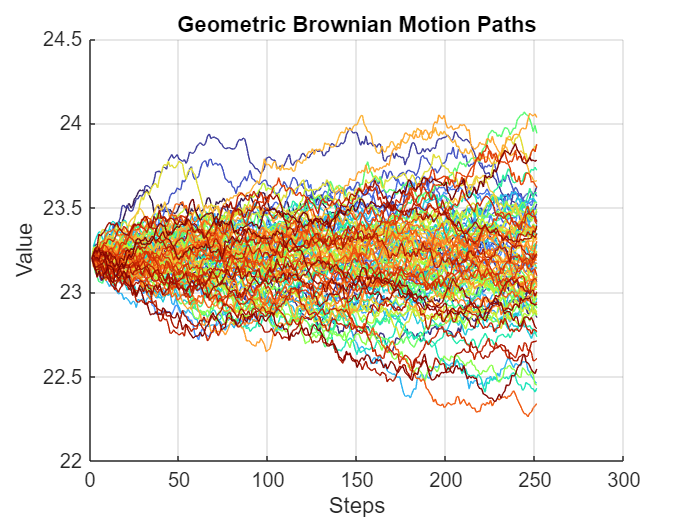

% I defined the parameters for the Geometric Brownian Motion simulation. These include the drift (mu),
% volatility (sigma), time step (dt), number of paths (npaths), number of steps (nsteps), and initial value (S0).
mu = 0.08 / 250;          % I set the drift rate for daily increments.
sigma = 0.25 / sqrt(250); % I calculated the daily volatility by scaling annualized sigma.
dt = 1 / 250;             % I chose a time step of one trading day (1/250th of a year).
npaths = 100;             % I simulated 100 independent paths.
nsteps = 250;             % I used 250 steps to represent a year of trading days.
S0 = 23.2;                % I set the initial stock price at 23.2, which serves as my starting point.

% I generated the Brownian Motion (BM) paths using random numbers.
epsilon = randn(nsteps, npaths); % I used normally distributed random numbers to model the randomness.
W = [zeros(1, npaths); sqrt(dt) * cumsum(epsilon)];
% Here, I initialized W with zeros (starting point) and calculated the cumulative sum of scaled random values.
% This step ensures the paths of the BM are continuous and start at zero.

% I calculated the Geometric Brownian Motion (GBM) paths from the BM paths.
t = (0:nsteps)' * dt; % I created a time vector from 0 to 1 year, with increments of dt.
Y = bsxfun(@plus, (mu - 0.5 * sigma^2) * t, sigma * W);
% I applied the exact solution to the SDE for GBM. The term (mu - 0.5 * sigma^2) accounts for the drift and volatility correction.
% The term sigma * W introduces the random fluctuations.
Y = S0 * exp(Y); % I exponentiated the results to convert them into GBM paths and scaled them by the initial value S0.

% I plotted the GBM paths with custom colors for better visualization.
figure; % I opened a new figure window to display the plot.
hold on; % I held the plot to overlay multiple lines on the same axes.
colormap turbo; % I selected the 'turbo' colormap for vibrant, high-contrast colors.
cmap = colormap; % I retrieved the colormap as an array of RGB values.
ncolors = size(cmap, 1); % I determined the number of unique colors available in the colormap.

% I looped through each path and assigned a unique color from the colormap.
for i = 1:npaths
    color_index = round((i / npaths) * (ncolors - 1)) + 1; % I mapped the path index to a colormap index.
    plot(Y(:, i), 'Color', cmap(color_index, :)); % I plotted each GBM path using its corresponding color.
end
hold off; % I stopped adding to the plot, so subsequent commands don’t affect it.

% I added titles and labels to make the plot more descriptive.
title('Geometric Brownian Motion Paths'); % I titled the plot to describe what it represents.
xlabel('Steps'); % I labeled the x-axis to show the progression of time in steps.
ylabel('Value'); % I labeled the y-axis to indicate the simulated price levels.

% I turned on the grid to make it easier to interpret the trends in the paths visually.
grid on;


% Interpretation of the Results:
% - The plot shows 100 GBM paths, each representing a possible price trajectory over a year.
% - The random fluctuations in the paths come from the Brownian Motion component.
% - Over time, the paths tend to diverge due to the compounding effects of the drift and volatility.
% - The range of paths illustrates the uncertainty in price predictions, consistent with stochastic processes.
